**Loading data and Plotting**

clear 
dir

.                    computeCost.m        featureNormaize.asv  gradientDescent.m    plotData.asv         
..                   ex1_compilation.mlx  featureNormaize.m    normalEqn.asv        plotData.m           
computeCost.asv      ex1data1.txt         gradientDescent.asv  normalEqn.m          



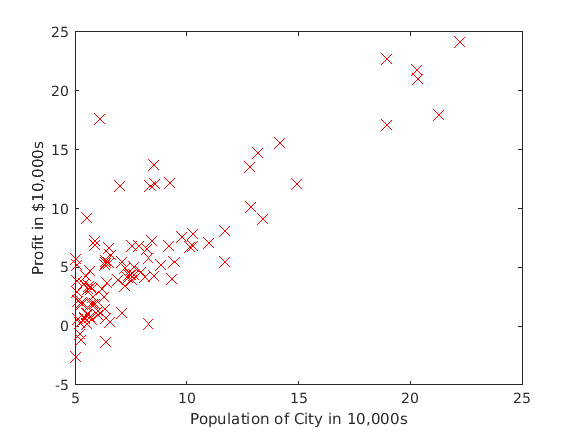

data = load('ex1data1.txt');
X = data(:,1);
y = data(:,2);
plotData(X,y);

**Initializing Values**

m = length(X);
X = [ones(m,1), data(:,1)];
theta = zeros(2,1);
iterations = 1500;
alpha = 0.01;

alpha = 0.0100

**Comouting Cost**

computeCost(X,y,theta);

computeCost(X,y,[-1;2]);

**Gradiaent Descent**

theta = gradientDescent(X,y,theta,alpha,iterations);
fprintf("Theta computed from gradient descent: \n%f, \n%f",theta(1),theta(2));

Theta computed from gradient descent: 
-3.630291, 
1.166362

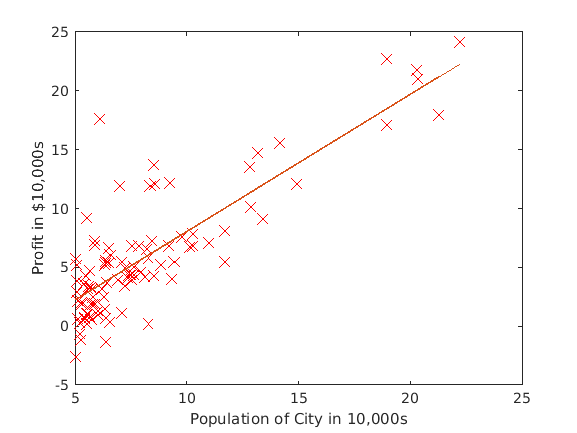

hold on;%keep previous plot visible
plot(X(:,2), X*theta,'-')
hold off%dont overlay anymore plots on this figure 

predict1 = [1,3.5]*theta;
fprintf('For population = 35,000 we predict a profit of %f\n', predict1*10000);

For population = 35,000 we predict a profit of 4519.767868


predict2 = [1,7]* theta;
fprintf('For population = 70,000 we predict a profit of %f\n', predict2*10000);

For population = 70,000 we predict a profit of 45342.450129


**Visualizing J(Theta)**

theta0_vals = linspace(-10,10,100);
theta1_vals = linspace(-1,4,100);
J_vals = zeros(length(theta0_vals), length(theta1_vals));
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
        t = [theta0_vals(i); theta1_vals(j)];
        J_vals(i,j) = computeCost(X,y,t);
    end
end

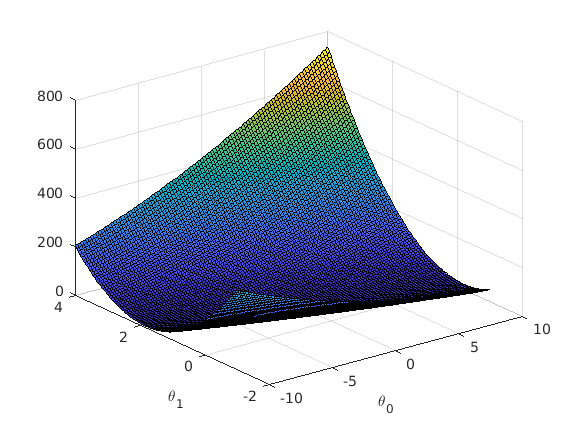

J_vals = J_vals';
figure;
%surface plot
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0');
ylabel('\theta_1');

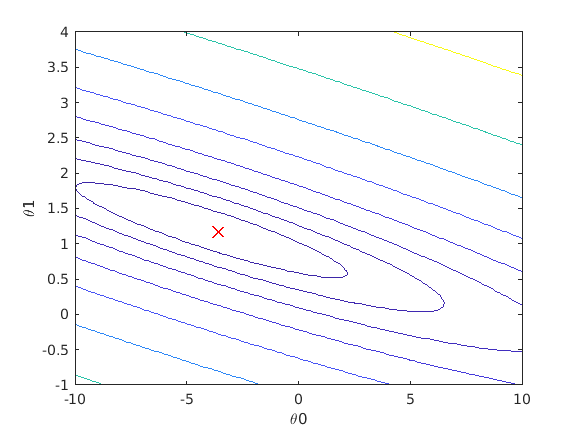


%contour plot
figure;
contour(theta0_vals,theta1_vals,J_vals, logspace(-2,3,20))
xlabel('\theta0');
ylabel('\theta1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;